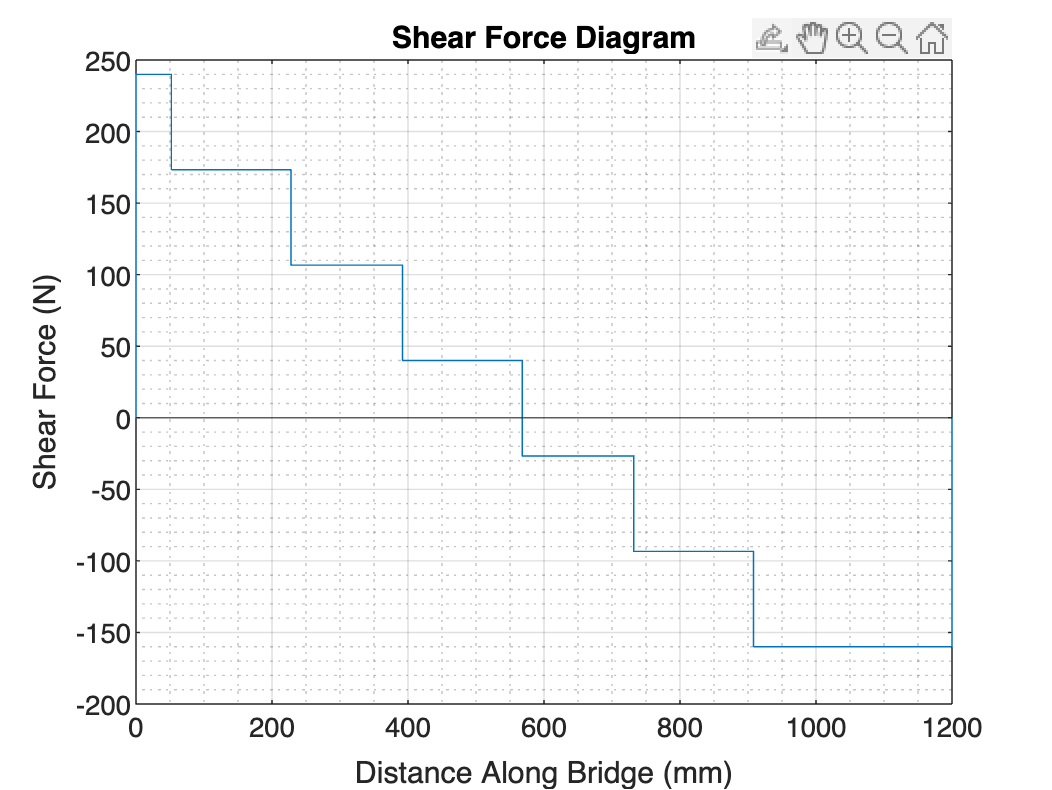

close all;
clear;

x = 0;

y_left = (720-x)/3;
y_right = (x+480)/3;

shear = zeros(1, 16);
shear(1) = 0;
shear(16) = 0;

x_shear = [0, 0, x+52, x+52, x+52+176, x+52+176, x+392, x+392, x+568, x+568, x+732, x+732, x+908, x+908, 1200, 1200];

for i = 1:7
    shear(2*i) = y_left - (200/3)*(i-1);
    shear(2*i+1) = y_left - (200/3)*(i-1);
end
shear;

moment = zeros(1,8);

moment(1) = 0;
moment(8) = 0;

x_moment = [0, x+52, x+52+176, x+392, x+568, x+732, x+908, 1200];


for i = 2:7
    x_val = (x_shear((i-1)*2+1)) - x_shear((i-1)*2-1);
    moment(i) = moment(i-1) + (shear((i-1)*2 + 1) * x_val);
end

moment;

figure
plot(x_shear, shear)
grid on
grid minor
yline(0)
xlabel("Distance Along Bridge (mm)")
ylabel("Shear Force (N)")
title("Shear Force Diagram")

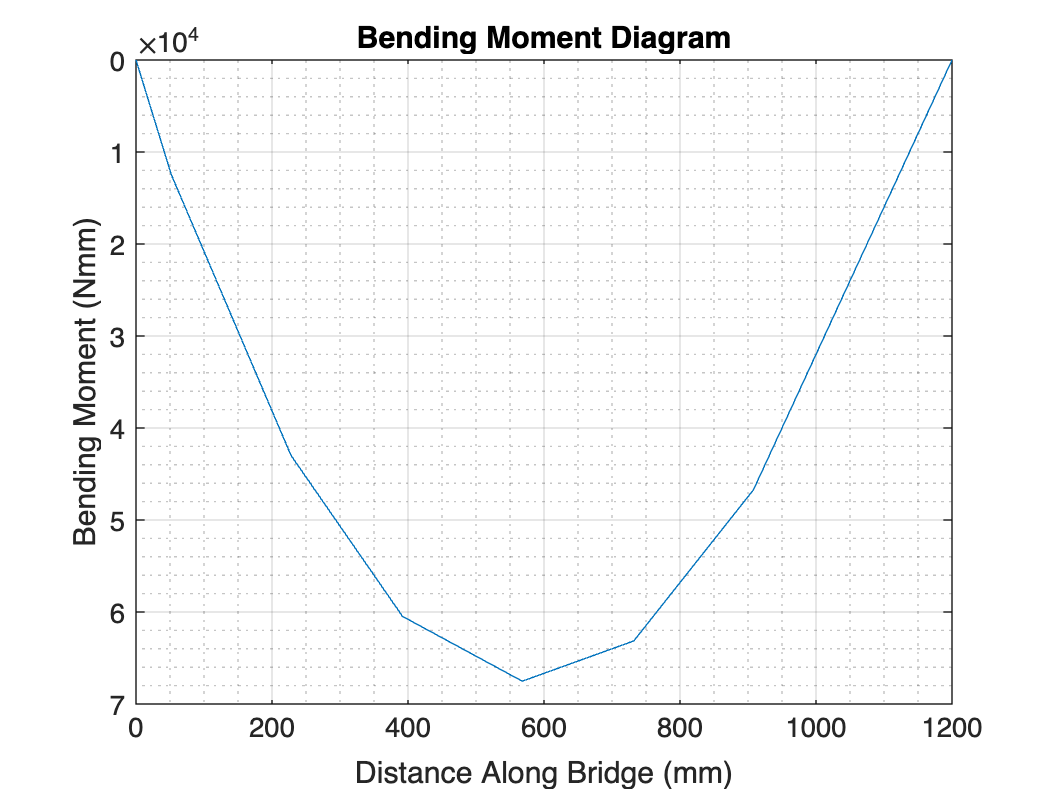


figure
plot(x_moment, moment)
grid on
grid minor
set(gca, 'YDir', 'reverse')  % Flip y-axis
xlabel("Distance Along Bridge (mm)")
ylabel("Bending Moment (Nmm)")
title("Bending Moment Diagram")